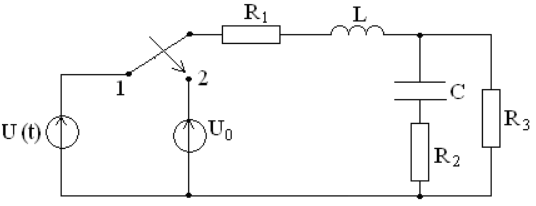

label = {'В';'Гц';'В';'Ом';'Ом';'Ом';'Гн';'Ф'};
val = [100;1500;50;60;70;80;30e-3;6e-6];
T = table(label,val,...
    'VariableNames',{'unit','value'},...
    'RowNames',{'U','fi','U_0','R_1','R_2','R_3','L_1','C_2'}...
    )

T = 8×2 table
           unit    value
           ____    _____

    U      'В'       100
    fi     'Гц'     1500
    U_0    'В'        50
    R_1    'Ом'       60
    R_2    'Ом'       70
    R_3    'Ом'       80
    L_1    'Гн'     0.03
    C_2    'Ф'     6e-06


Вычисления при положении рубильника в позиции 1

omeg = 2*pi*T{'fi','value'};  %расчет угловой скорости
X_R_1 = T{'R_2','value'};   %расчет реактивного сопротивлнения элементов
X_R_2 = T{'R_2','value'};
X_R_3 = T{'R_3','value'};
X_L_1 = omeg * T{'L_1','value'} *i;
X_C_2 = 1/(omeg*T{'C_2','value'}*i);

Z_2 = X_C_2+X_R_2;  %расчет суммарного сопротивления на ветвях
Z_3 = X_R_3;
Z_23 = (1/Z_2 + 1/Z_3)^-1;
Z = Z_23+X_L_1+X_R_1

Z = 1.0792e+02 + 2.7778e+02i

I = T{'U','value'}/Z    %расчет тока на главной ветви

I = 0.1215 - 0.3128i


I_2 = I*(Z_3/(Z_3+Z_2))     %расчет тока на 2 ветви

I_2 = 0.0833 - 0.1570i

I_3 = I*(Z_2/(Z_2+Z_3))     %расчет тока на 3 ветви

I_3 = 0.0382 - 0.1558i

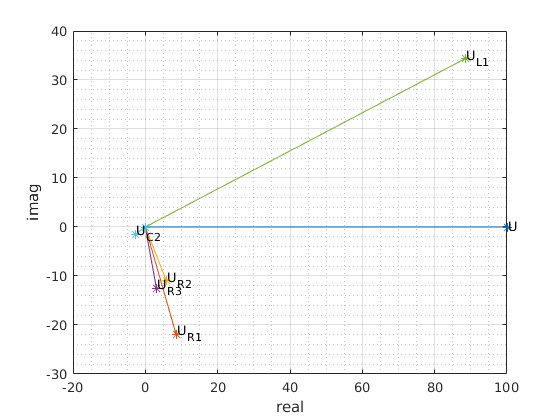

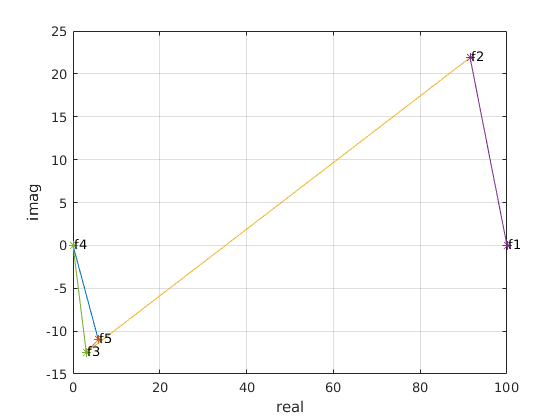

U_R_1 = I*X_R_1;    %расчет напряжений на каждом элементе
U_R_2 = I_2*X_R_2;
U_R_3 = I_3*X_R_3;
U_L_1 = I*X_L_1;
U_C_2 = I_2*X_C_2;
%построение графиков
imag2plot({T{'U','value'} U_R_1 U_R_2 U_R_3 U_L_1 U_C_2},{'U' 'U_R_1' 'U_R_2' 'U_R_3' 'U_L_1' 'U_C_2'})

f4 = 0;  %расчет потенциалов
f5 = f4+U_R_2;
f3 = f5+U_C_2;
f3 = f4+U_R_3;
f2 = f3+U_L_1;
f1 = f2+U_R_1;
f4 = f1-T{'U','value'};
imag2plot_2({{f4 f5 f3 f2 f1} {f4 f3}},{{'f4' 'f5' 'f3' 'f2' 'f1'} {'f4' 'f3'}})

Расчет в положении рубильника в позиции 2

При постоянном напряжении катушки индуктивности считается как обычный резистор, принимая во внимание его паразитное сопротивление, но в задании не дали данный параметр, по этому в расчетах мы не будем учитывать катушки индуктивности.

С конденсатором все намного проще, при постоянном напряжении он представляет из себя обрыв сети. Соответственно ветвь с конденсатором так-же не будет учитываться.

R = T{'R_1','value'}+T{'R_3','value'}

R = 140

I = T{'U_0','value'}/R

I = 0.3571

U_0_R_1 = I*T{'R_1','value'}

U_0_R_1 = 21.4286

U_0_R_3 = I*T{'R_3','value'}

U_0_R_3 = 28.5714

imag2plot({T{'U','value'} U_0_R_1 U_0_R_3},{'U' 'U_R_1' 'U_R_3'})
f_0_3 = 0;
f_0_2 = f_0_3+U_0_R_3;
f_0_1 = f_0_2+U_0_R_1;
f_0_3 = f_0_1 - T{'U','value'}

f_0_3 = -50

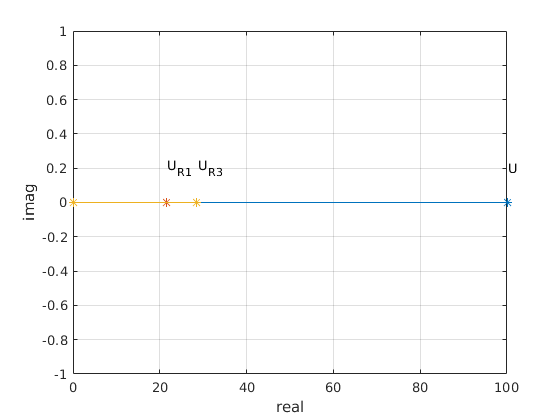

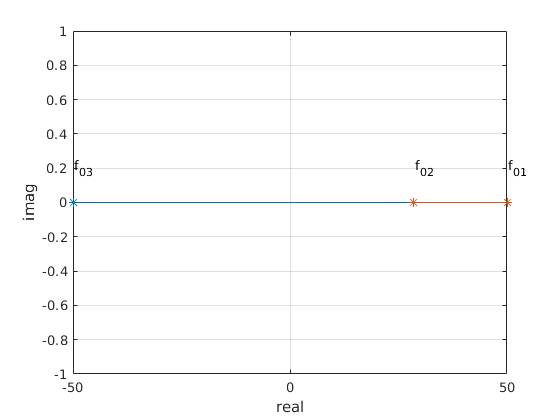

imag2plot_2({{f_0_3 f_0_2 f_0_1}},{{'f_0_3' 'f_0_2' 'f_0_1'}})